# Actividad 1: Mapeo de coordenadas

Daniel Ruán Aguilar - A01731921

En esta actividad se genera un mapeo del siguiente sistema global al sistema local de referencia del robot móvil y viceversa.

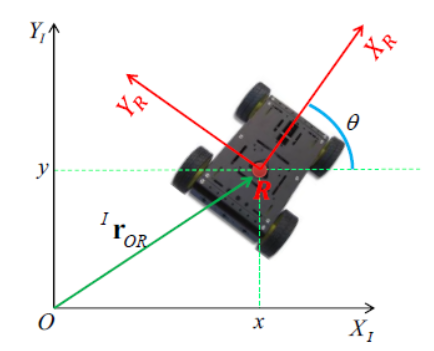

Imagen 1.

Posteriormente se realiza el mapeo de coordenadas inerciales, hacia un marco de referencia local y comprobar si se obtienen las coordenadas iniciales con el mapeo inverso.

%Limpieza de pantalla
clear all
close all
clc

tic

Priimero se realiza la transformación de manera simbólica con la declaración de variables simbólicas.

syms x(t) y(t) th(t)  t 

 %Creamos el vector de posición
  xi_inercial= [x; y; th];
  disp('Coordenadas generalizadas');

Coordenadas generalizadas


  pretty (xi_inercial);

/  x(t) \
|       |
|  y(t) |
|       |
\ th(t) /



 %Creamos el vector de velocidades derivando la posición
  xip_inercial= diff(xi_inercial, t);
  disp('Velocidades generalizadas');

Velocidades generalizadas


  pretty (xip_inercial);

/   d      \
|  -- x(t) |
|  dt      |
|          |
|   d      |
|  -- y(t) |
|  dt      |
|          |
|  d       |
| -- th(t) |
\ dt       /



Se defino el vector de posición y la matriz de rotación sobre el eje z. 

En el eje z no hay movimiento, únicamente la rotación indicada con el ángulo.

P(:,:,1)= [x;y;th]; %Viene siendo "xi_inercial"

R(:,:,1)= [cos(th) -sin(th)  0;
           sin(th)  cos(th)  0;
           0        0        1];


Se realiza la transformación del marco de referencia global al local con la siguiente fórmula.

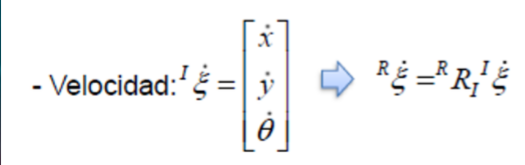 

Fórmula 1.

En la cual se observa que para encontrar la xi local se debe multiplicar la matriz de rotación por la de posición.

xi_local=R(:,:,1)*P(:,:,1)

$$xi\_local = \left(\begin{array}{c} \cos\left(\mathrm{th}\left(t\right)\right)\,x\left(t\right)-\sin\left(\mathrm{th}\left(t\right)\right)\,y\left(t\right)\\ \cos\left(\mathrm{th}\left(t\right)\right)\,y\left(t\right)+\sin\left(\mathrm{th}\left(t\right)\right)\,x\left(t\right)\\ \mathrm{th}\left(t\right) \end{array}\right)$$

Ahora se presentan diferentes ejemplos de coordenadas para transformar con valores que ya no son simbólicos.

%a)
%Defino coordenadas inerciales 1
x1 = -5;    % Posicion inicial eje x
y1 = 9;   % Posicion inicial eje y
th1= -2;   % Orientacion inicial del robot

%b)
%Defino coordenadas inerciales 2
x2 = -3;    % Posicion inicial eje x
y2 = 8;   % Posicion inicial eje y
th2= 63;   % Orientacion inicial del robot

%c)
%Defino coordenadas inerciales 3
x3 = 5;    % Posicion inicial eje x
y3 = -2;   % Posicion inicial eje y
th3= 90;   % Orientacion inicial del robot

%d)
%Defino coordenadas inerciales 4
x4 = 0;    % Posicion inicial eje x
y4 = 0;   % Posicion inicial eje y
th4= 180;   % Orientacion inicial del robot

%e)
%Defino coordenadas inerciales para un tiempo 5
x5 = -6;    % Posicion inicial eje x
y5 = 3;   % Posicion inicial eje y
th5= -55;   % Orientacion inicial del robot


Se repite el mismo procedimiento que se usó en las variables simbólicas pero esta vez se incluye la obtención de la matriz inversa para regresar la transformación de las coordenadas locales a inerciales y comprobar si nuestro resultado es correcto.

%Defino mi vector de posición y matriz de rotación
Pos_1=[x1; y1; th1];
Rot_1= [cos(th1) -sin(th1) 0;
        sin(th1)  cos(th1) 0;
        0         0      1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =    10.2644
    0.8012
   -2.0000


%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 10.2956

%Se invierte la matriz de rotación 
inv_Rot_1= inv(Rot_1);
% y se multiplica por la local para obtener la inercial y comprobamos.
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =    -5.0000
    9.0000
   -2.0000


%Defino mi vector de posición y matriz de rotación
Pos_2=[x2; y2; th2];
Rot_2= [cos(th2) -sin(th2) 0;
        sin(th2)  cos(th2) 0;
        0         0      1];
 
%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_2=Rot_2*Pos_2

xi_local_2 =    -4.2965
    7.3851
   63.0000


%Obtengo la magnitud del vector resultante 
magnitud2= sqrt(xi_local_2(1)^2 + xi_local_2(2)^2)

magnitud2 = 8.5440

%Se invierte la matriz de rotación 
inv_Rot_2= inv(Rot_2);
% y se multiplica por la local para obtener la inercial y comprobamos.
xi_inercial_2= inv_Rot_2*xi_local_2

xi_inercial_2 =     -3
     8
    63



%Defino mi vector de posición y matriz de rotación
Pos_3=[x3; y3; th3];
Rot_3= [cos(th3) -sin(th3) 0;
        sin(th3)  cos(th3) 0;
        0         0      1];
 
%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_3=Rot_3*Pos_3

xi_local_3 =    -0.4524
    5.3661
   90.0000



%Obtengo la magnitud del vector resultante 
magnitud3 = sqrt(xi_local_3(1)^2 + xi_local_3(2)^2)

magnitud3 = 5.3852

%Se invierte la matriz de rotación 
inv_Rot_3= inv(Rot_3);
% y se multiplica por la local para obtener la inercial y comprobamos.
xi_inercial_3= inv_Rot_3*xi_local_3

xi_inercial_3 =     5.0000
   -2.0000
   90.0000


%Defino mi vector de posición y matriz de rotación
Pos_4=[x4; y4; th4];
Rot_4= [cos(th4) -sin(th4) 0;
        sin(th4)  cos(th4) 0;
        0         0      1];
 
%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_4=Rot_4*Pos_4

xi_local_4 =      0
     0
   180



%Obtengo la magnitud del vector resultante 
magnitud4= sqrt(xi_local_4(1)^2 + xi_local_4(2)^2)

magnitud4 = 0

%Se invierte la matriz de rotación 
inv_Rot_4= inv(Rot_4);
% y se multiplica por la local para obtener la inercial y comprobamos.
xi_inercial_4= inv_Rot_4*xi_local_4

xi_inercial_4 =      0
     0
   180



%Defino mi vector de posición y matriz de rotación
Pos_5=[x5; y5; th5];
Rot_5= [cos(th5) -sin(th5) 0;
        sin(th5)  cos(th5) 0;
        0         0      1];
 
%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_5=Rot_5*Pos_5

xi_local_5 =    -3.1320
   -5.9322
  -55.0000


%Obtengo la magnitud del vector resultante 
magnitud5= sqrt(xi_local_5(1)^2 + xi_local_5(2)^2)

magnitud5 = 6.7082

%Se invierte la matriz de rotación 
inv_Rot_5= inv(Rot_5);
% y se multiplica por la local para obtener la inercial y comprobamos.
xi_inercial_5= inv_Rot_5*xi_local_5

xi_inercial_5 =    -6.0000
    3.0000
  -55.0000


%tiempo recopilado del programa
 toc

Elapsed time is 2.770402 seconds.
